**Data**

% Set up the Import Options and import the data
opts2 = delimitedTextImportOptions("NumVariables", 15);

% Specify range and delimiter
opts2.DataLines = [2, Inf];
opts2.Delimiter = ",";

% Specify column names and types
opts2.VariableNames = ["Var1", "Time", "Speed", "RPM", "nGear", "Throttle", "Brake", "DRS", "X", "Y", "Z", "Status", "Time1", "Status1", "Message"];
opts2.VariableTypes = ["double", "string", "double", "double", "double", "double", "categorical", "double", "double", "double", "double", "categorical", "string", "double", "categorical"];

% Specify file level properties
opts2.ExtraColumnsRule = "ignore";
opts2.EmptyLineRule = "read";

% Specify variable properties
opts2 = setvaropts(opts2, ["Time", "Time1"], "WhitespaceRule", "preserve");
opts2 = setvaropts(opts2, ["Time", "Brake", "Status", "Time1", "Message"], "EmptyFieldRule", "auto");

% Import the data
data = readtable("C:\Users\berke\OneDrive\Masaüstü\Performance Degradation Project\2023 Data\2023_RB_VER_1.csv", opts2);

% Clear temporary variables
clear opts2

% Display results
data

data = 21505×15 table
    Var1              Time              Speed     RPM     nGear    Throttle    Brake    DRS     X       Y       Z      Status              Time1              Status1      Message  
    ____    ________________________    _____    _____    _____    ________    _____    ___    ____    ____    ____    _______    ________________________    _______    ___________

      0     "0 days 00:00:00.110000"       0     10130      1         16       False     1     -280    35

data = data(data.Time ~= "",:);
data = data(:,1:11);
data = renamevars(data,["Var1" "nGear"],["DataPoint" "Gear"]);

**Converting Time Strings to Second Format**

timeStr = data.Time;
% Split into 'days' and 'time' parts
parts = split(timeStr, " ");
days = str2double(parts(:, 1)); % Extract days as numeric
timePart = parts(:, 3); % Extract the 'hhmmss.SSSSSS' part
data.Time=datetime(timePart,'InputFormat','HH:mm:ss.SSSSSS','Format','HH:mm:ss.SSS');
% Extract hours, minutes, and seconds from datetime
hours = hour(data.Time); 
minutes = minute(data.Time); 
seconds = second(data.Time); 
timeInSeconds = hours * 3600 + minutes * 60 + seconds;
data.Time = timeInSeconds

data = 20975×11 table
    DataPoint    Time    Speed     RPM     Gear    Throttle    Brake    DRS     X       Y       Z  
    _________    ____    _____    _____    ____    ________    _____    ___    ____    ____    ____

        0        0.11       0     10130     1         16       False     1     -280    3559    -157
        1        0.31       0      9766     1         16       False     1     -280    3559    -157
        2        0.59       2      8086     1         16       False     1     -280    3559    -157
        3        0.95      16      5566     1         16       False     1     -280    3564    -157
   

**Determining Straight Lines**

% Data for full throttle, No DRS and No Braking
allGasMask = (data.Throttle == 100) & (data.DRS ~=12) & (data.DRS ~=14) & (data.Brake == "False");
allGas = data(allGasMask, :)

allGas = 9129×11 table
    DataPoint    Time     Speed     RPM     Gear    Throttle    Brake    DRS     X       Y       Z  
    _________    _____    _____    _____    ____    ________    _____    ___    ____    ____    ____

       17        4.029     124     11303     3        100       False     1     -252    4319    -158
       18         4.27     142     11726     3        100       False     1     -247    4448    -158
       19         4.63     156     11813     3        100       False     1     -245    4522    -158
       20         4.83     165     10553     3        100       False     1     -241    4629    -

distances = sqrt(diff(allGas.X).^2 + diff(allGas.Y).^2 + diff(allGas.Z).^2)

distances = 1.0e+03 *

    0.1291
    0.0740
    0.1071
    0.1961
    0.2181
    0.1721
    0.0941
    0.1801
    0.0490
    0.1761


% Threshold for straight-line zones
straightLineThreshold = 1500; 
straightLineMask = [true; distances < straightLineThreshold]; 
zoneLabels = zeros(height(allGas), 1);
currentZone = 1 

currentZone = 1

zoneLabels(1) = currentZone; % First point is part of the first zone
for i = 2:height(allGas)
    if distances(i-1) < straightLineThreshold && (allGas.DataPoint(i) - allGas.DataPoint(i-1)) <= 1
        zoneLabels(i) = currentZone;
    else 
        currentZone = currentZone + 1;
        zoneLabels(i) = currentZone;
    end
end
allGas.Zone = zoneLabels;

**Clustering Straight Line Zones**

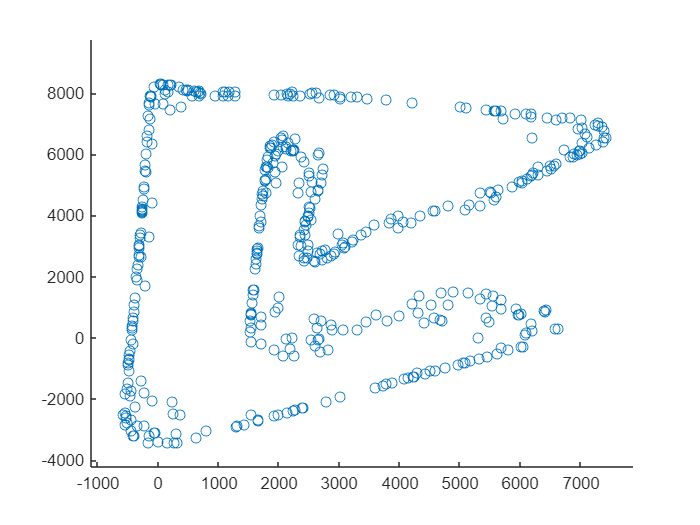

uniqueZones = unique(allGas.Zone);
zoneCentroids = zeros(length(uniqueZones), 3);
for i = 1:length(uniqueZones)
    zonePoints = allGas(allGas.Zone == uniqueZones(i), :);
    zoneCentroids(i, :) = mean([zonePoints.X, zonePoints.Y, zonePoints.Z], 1);
end
zoneCentroidsX=zoneCentroids(:,1);
zoneCentroidsY=zoneCentroids(:,2);
scatter(zoneCentroidsX,zoneCentroidsY)

epsilon = 0;
% Distance threshold (epsilon) and minimum points for DBSCAN
if (allGas.DataPoint(i) - allGas.DataPoint(i-1)) == 1
        epsilon = epsilon + sqrt(diff(allGas.X).^2 + diff(allGas.Y).^2 + diff(allGas.Z).^2);
end
epsilon = mean(epsilon)+50;
minPts = 10;
% DBSCAN
zoneGroups = dbscan(zoneCentroids, epsilon, minPts);

% Assign the cluster labels back to the zones
for i = 1:length(uniqueZones)
    % Update the dataset with the cluster group
   allGas.Cluster(allGas.Zone == uniqueZones(i)) = zoneGroups(i);
end
allGas

allGas = 9129×13 table
    DataPoint    Time     Speed     RPM     Gear    Throttle    Brake    DRS     X       Y       Z      Zone    Cluster
    _________    _____    _____    _____    ____    ________    _____    ___    ____    ____    ____    ____    _______

       17        4.029     124     11303     3        100       False     1     -252    4319    -158     1        -1   
       18         4.27     142     11726     3        100       False     1     -247    4448    -158     1        -1   
       19         4.63     156     11813     3        